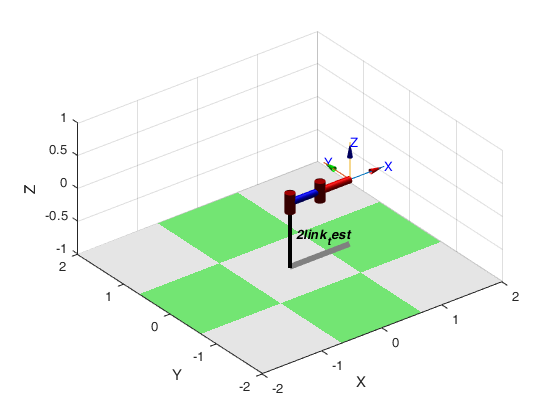

import ETS2.*
clc
clear;
%% set link
syms q1 q2 real
%%%%     J.ang  J.ext(z)  J.off(x)   J.twist(x)   J.rev   displacemnet %%
%%%%         the  D    A  Alp  SIG  OFF     %%%%% 
L(1) = Link([ 0 0 0.5 0 0 0], 'standard');
L(2) = Link([ 0 0 0.5 0 0 0], 'standard');
%Robot = SerialLink(L, 'name', 'two link');
Robot = SerialLink(L);
Robot.name = '2link_test';
clkTE = Robot.fkine([q1 q2]);
Robot.plot([0, 0], 'deg', 'tilesize', 2)

clkTE.t(1,1)

$$ans = \frac{\cos\left(q_{1}+q_{2}\right)}{2}+\frac{\cos\left(q_{1}\right)}{2}$$

clkTE.t(2,1)

$$ans = \frac{\sin\left(q_{1}+q_{2}\right)}{2}+\frac{\sin\left(q_{1}\right)}{2}$$

ik_sol = Robot.ikine(SE3(0.5,0.5,0),'mask',[1 1 0 0 0 0]);
ik_sol

ik_sol =     0.0000    1.5708


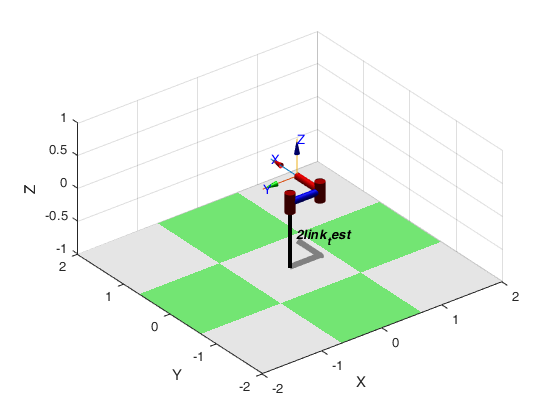

%Robot.plot(ik_sol, 'tilesize',2)

hold on 
%Robot.plot([0, 0], 'deg', 'tilesize', 2)
q0 =[0,0];
qf =[0, 1.5708];
qtg = jtraj(q0,qf,100);
for q =qtg' 
Robot.plot(q');
end
hold off

x = 1:1:100

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y = qtg(x,2)

y =          0
    0.0000
    0.0001
    0.0004
    0.0010
    0.0019
    0.0032
    0.0050
    0.0073
    0.0103


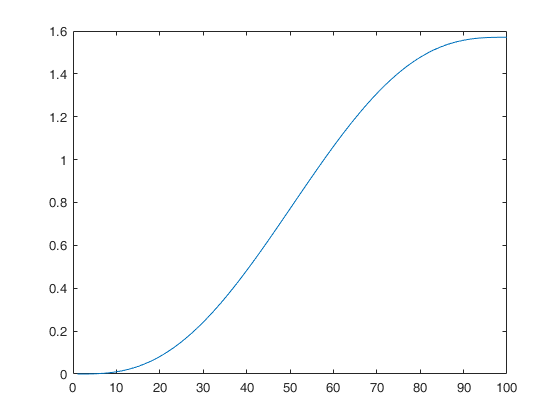

plot(x, y)